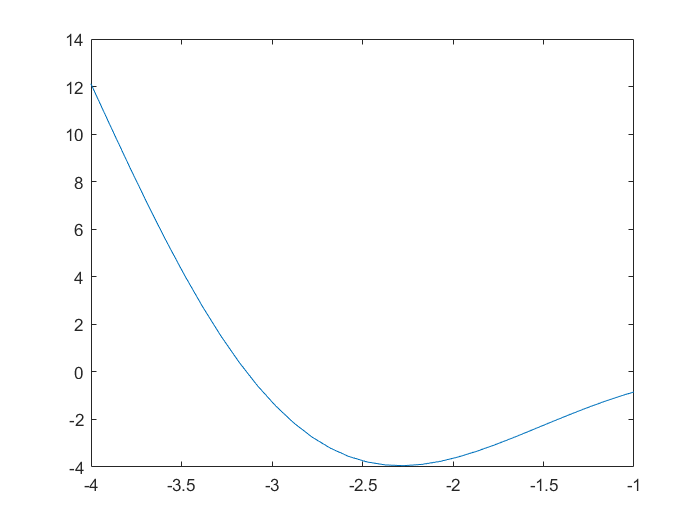

f = @(x) x.^2.*sin(x);
x = linspace(-5, 5);
plot(x, f(x));
xlim([-4, -1]);


minx = fminbnd(f, -3, -1)

minx = -2.2889

f(minx)

ans = -3.9453

[mix, minf] = fminbnd(f, -3, -1)

mix = -2.2889

minf = -3.9453

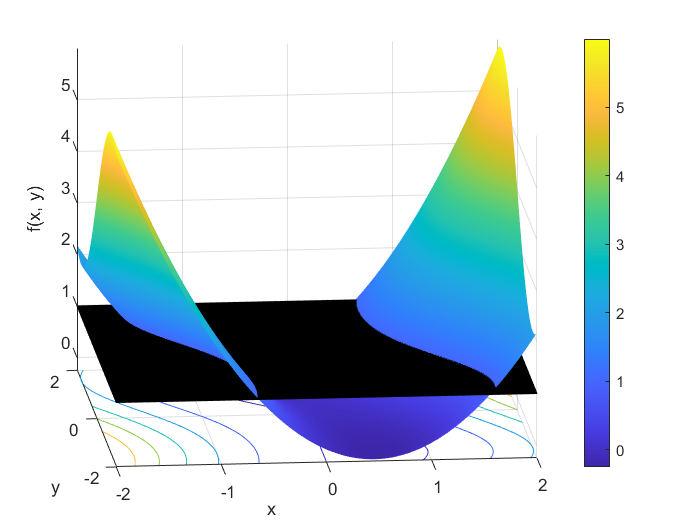

figure
f = @(x, y) x.^2 + x.*sin(y);
x = linspace(-2, 2, 100);
y = linspace(-2, 2, 100);
[X, Y] = meshgrid(x,y);
surfc(X, Y, f(X, Y))
xlabel('x');
ylabel('y');
zlabel('f(x, y)');
shading interp
colorbar
hold on;
onex = ones(size(X));
surf(X, Y, onex*1);
% contourf(X, Y, f(X,Y));
colorbar